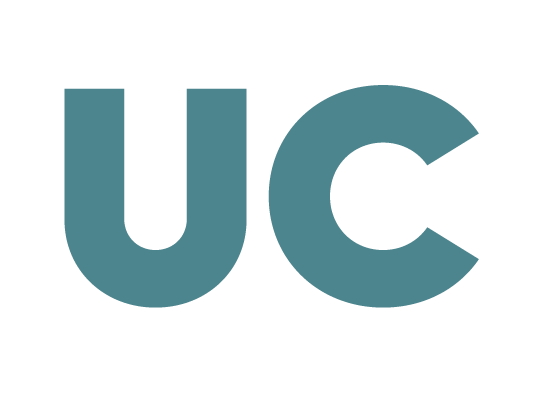

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometría**

# **Práctica 10: Aplicaciones lineales (I)**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Objetivos**

- Obtención de la matriz de una aplicación lineal

- Cálculo del núcleo y la imagen de una aplicación lineal

## **Matriz asociada a una aplicación lineal**

Sea $f$ la siguiente aplicación lineal:


$$\mathit{f}: \mathbb{R}^3 \longrightarrow  \mathbb{R}^2 \\
(x,y,z) \leadsto (x'=2x, y'=-3y+z) $$


Siempre podremos reescribirla en la forma $\vec{x'}=A\vec{x}$ del siguiente modo:


$$\left\lbrack \begin{array}{c}
x^{\prime } \\
y^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
2 & 0 & 0\\
0 & -3 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack$$


Siendo $A$ su matriz asociada en bases canónicas (o matriz estándar). Fíjate que al ser una aplicación lineal que va de $\mathbb{R}^3$ en $\mathbb{R}^2$, $A$ es de tamaño $2 \times 3$. Una vez tenemos $A$, es muy fácil calcular el transformado (es decir, la imagen), de cualquier vector del espacio vectorial inicial, $\mathbb{R}^3$. Por ejemplo, la imagen del vector $(5,-7,-\pi)$ de $\mathbb{R}^2$ será:

A = [2 0 0; 0 -3 1]  % matriz estándar de f

A*[5 -7 -pi]'  % imagen mediante f del vector (5, -7, -pi)

Se puede comprobar fácilmente que las columnas de $A$ se corresponden con la imagen mediante $f$ de los vectores de la base canónica del espacio inicial:

A*[1 0 0]'  % primera columna de A (imagen del primer  vector de la BC de R³)
A*[0 1 0]'  % segunda columna de A (imagen del segundo vector de la BC de R³)
A*[0 0 1]'  % tercera columna de A (imagen del tercer  vector de la BC de R³)

## **Núcleo e imagen de la aplicación lineal**

Una vez tenemos la matriz de la aplicación, es muy fácil hallar su núcleo (o *kernel*). Recuerda que el núcleo lo forman los vectores del espacio inicial cuya imagen mediante $f$ es el $\vec{0}$ del espacio final. Por tanto, partiendo de la matriz estándar $A$, nuestro problema se reducirá a resolver el sistema homogéneo cuya matriz de coeficientes es precisamente $A$, lo que nos devolverá directamente una base de $Ker(f)$:

baseKer = null(A, 'r')  % base de Ker(f) --> dim(Ker(f))=1

Para comprobar que la base que hemos obtenido es correcta, podríamos ver que la imagen del vector que la forma es el $\vec{0}$de $\mathbb{R}^2$:

A*baseKer  % al aplicarle A a la base de Ker(f), obtengo el vector 0 de R²

Por otro lado, sabemos que $Im(f)$ es el subespacio generado por las columnas de $A$, por lo cual, una base de $Im(f)$ será la formada por las columnas de $A$ que sean linealmente independientes:

 [ ared j ] = rref(A)  % sólo hay dos columnas L.I. en A, la primera y la segunda
baseImf=A(: , j) 

Date cuenta de que se cumple la relación de dimensiones $dim(Ker(f))+dim(Im(f))=n$, donde $n$ es la dimensión del espacio vectorial inicial. En nuestro caso particular tendríamos $1+2=3$. Además, por definición, $rg(f)=rg(A)=dim(Im(f))$.